# **Control PID - Modelo de Hovorka**

**Elaborado por: **Manuela María Muriel Tobar, David Andrés Ojeda Guzmán

**Universidad de Nariño**

Este script simula el control de la glucosa en sangre utilizando un modelo fisiológico de tipo Hovorka combinado con un controlador PID. Se considera una referencia de glucosa variable a lo largo del día, así como la absorción de carbohidratos debida a tres comidas principales. El sistema incluye la acción de bolos de insulina aplicados antes de las comidas y la regulación continua mediante el PID. Al finalizar la simulación, se grafican las principales variables fisiológicas y se evalúan métricas de desempeño y control glucémico clínicamente relevantes.

clear variables; close all; clc;

Calcula el punto de equilibrio del modelo no lineal de Hovorka y, alrededor de él, obtiene la versión lineal (matrices **A**, **B**, **C**, **D**).  Esto nos permite utilizar herramientas lineales ‑como `pidtune`‑ para sintonizar un controlador clásico sobre un sistema originalmente no lineal.

%% 1. Linealización y sintonía PID
[A, B, C, D, x_eq, ub, p] = linearizar_hovorka();

Equilibrio 100 mg/dL → u_basal = 0.0022 U/min


sys = ss(A, B, C, D);
Cpid = pidtune(sys, 'PID');
Kp = Cpid.Kp;
Ki = Cpid.Ki;
Kd = Cpid.Kd;
fprintf('--- Ganancias PID ---\n');

--- Ganancias PID ---


fprintf('Kp = %.4f\n', Kp);

Kp = -0.0002


fprintf('Ki = %.4f\n', Ki);

Ki = -0.0000


fprintf('Kd = %.4f\n', Kd);

Kd = -0.0161


fprintf('---------------------\n\n');

---------------------



%% 2. Configuración de comidas y bolos
meal_times = [8 12 20] * 60;
carb_grams = [60 70 60];     
BW = 70;                     

ICR = 10;                     % Relación Insulina-Carbohidratos
bolus_U = carb_grams / ICR;   % Unidades de insulina para cada bolo
bolus_t = meal_times - 30;    % Bolo administrado 30 min antes de las comidas
bolus_len = 5;                % duración de la administración del bolo

u_maxPID = 10;              %Máxima tasa de insulina basal permitida por el controlador PID (U/min)
u_maxBOL = 0.3;              % Máxima tasa de administración de un bolo de insulina (U/min)

Esta función representa la dinámica completa del sistema en lazo cerrado. Combina el modelo fisiológico de Hovorka con el controlador PID, generando la derivada del estado en función del estado actual y el tiempo. Aquí se calcula tanto el efecto del controlador PID como la inyección de insulina prandial (bolos) antes de las comidas. También se impone la saturación de insulina tanto para el controlador como para los bolos, garantizando que las tasas no excedan límites fisiológicos. Esta función es la que se integra en el tiempo mediante `ode45` durante la simulación.

%% 3. Simulación
t_end = 24 * 60; 
y0 = [x_eq; 0]; 

odefun = @(t, s) rhs_closed(t, s, Kp, Ki, Kd, p, meal_times, carb_grams, BW,bolus_t, bolus_U, bolus_len,u_maxPID, u_maxBOL);

[t, sol] = ode45(odefun, [0 t_end], y0);

%% 4. Cálculo de señales derivadas
t_h = t / 60;                                       % Tiempo en horas
G_mgdL = sol(:, 1) / p.VG * 18;                     % Glucosa plasmática en mg/dL
ref_vec = arrayfun(@smooth_glucose_reference, t);   % Referencia de glucosa variable en mg/dL
I_pl = sol(:, 5);                                   % Insulina plasmática
x1 = sol(:, 6);                                     % Acción de la insulina 1
x2 = sol(:, 7);                                     % Acción de la insulina 2
x3 = sol(:, 8);                                     % Acción de la insulina 3
UG_series = arrayfun(@(ti) Ra_meal(ti, meal_times, carb_grams, p, BW), t); % Tasa de absorción de glucosa de las comidas
UI_series = sol(:, 4) / p.tmaxI;                    % Tasa de aparición de insulina subcutánea
Q1_series = sol(:, 1);                              % Glucosa en el compartimento 1 (plasma y tejidos de equilibrio rápido)
Q2_series = sol(:, 2);                              % Glucosa en el compartimento 2 (tejidos de equilibrio lento)

% Señal de control total de insulina
u_tot = arrayfun(@(ii) u_total(t(ii), sol(ii, :), ...
    Kp, Ki, Kd, p, meal_times, carb_grams, BW, ...
    bolus_t, bolus_U, bolus_len, ...
    u_maxPID, u_maxBOL), 1:numel(t));

Al finalizar la simulación, se evalúan métricas que permiten cuantificar el rendimiento del controlador. Los índices de desempeño IAE, ISE e ITAE miden el error acumulado con respecto a la referencia en distintas formas (valor absoluto, cuadrático y ponderado por tiempo). Por otro lado, las métricas glucémicas —como el porcentaje de tiempo en rango (TIR), hipoglucemia, hiperglucemia y coeficiente de variación (CV)— son estándares clínicos para evaluar la calidad del control glucémico. Estos valores ayudan a comparar distintas estrategias de control bajo condiciones realistas.

%% 5. Índices de desempeño (IAE, ISE, ITAE)
e_abs = abs(G_mgdL - ref_vec);         
e_sq  = (G_mgdL - ref_vec).^2;         

IAE  = trapz(t,  e_abs);                
ISE  = trapz(t,  e_sq);                 
ITAE = trapz(t,  t .* e_abs);           

fprintf('--- Índices de desempeño ---\n');

--- Índices de desempeño ---


fprintf('IAE  = %.2f',  IAE);

IAE  = 66931.59

fprintf('ISE  = %.2f', ISE);

ISE  = 4332188.53

fprintf('ITAE = %.2f ', ITAE);

ITAE = 49259303.53 

%% 6. Métricas glucémicas
in_range =  (G_mgdL >=  70) & (G_mgdL <= 180);
hypo     =  (G_mgdL <   70);
hyper    =  (G_mgdL >  180);

TIR_pct  = 100 * sum(in_range) / numel(G_mgdL);
HIPO_pct = 100 * sum(hypo)     / numel(G_mgdL);
HIPER_pct= 100 * sum(hyper)    / numel(G_mgdL);
CV_pct   = 100 * std(G_mgdL)   / mean(G_mgdL);

fprintf('--- Métricas glucémicas ---\n');

--- Métricas glucémicas ---


fprintf('TIR   = %.1f %%\n', TIR_pct);

TIR   = 61.2 %


fprintf('Hipo  = %.1f %%\n', HIPO_pct);

Hipo  = 0.0 %


fprintf('Hiper = %.1f %%\n', HIPER_pct);

Hiper = 38.8 %


fprintf('CV    = %.1f %%\n\n', CV_pct);

CV    = 19.3 %



LW = 2.5; 

%% 7. Gráfico de panel (Diseño 4x2)
figure('Name', 'Panel completo (ref variable)', 'Position', [60 60 1200 800]);

subplot(4, 2, 1);
hold on;
grid on;
hGluc = plot(t_h, G_mgdL, 'b', 'LineWidth', LW);      
hRef = plot(t_h, ref_vec, '--k', 'LineWidth', LW);   
for m = meal_times
    xline(m / 60, '--g', 'LineWidth', 1.2); 
end
xlim([0.0 24])

yline(70, '--r', 'LineWidth', 1.2);
yline(180, '--r', 'LineWidth', 1.2);


title('Glucosa plasmática');
ylabel('mg/dL');

legend([hGluc hRef], ...
       {'Glucosa', 'Referencia', 'Comidas'}, ...
       'Location', 'northwest', 'NumColumns', 1);

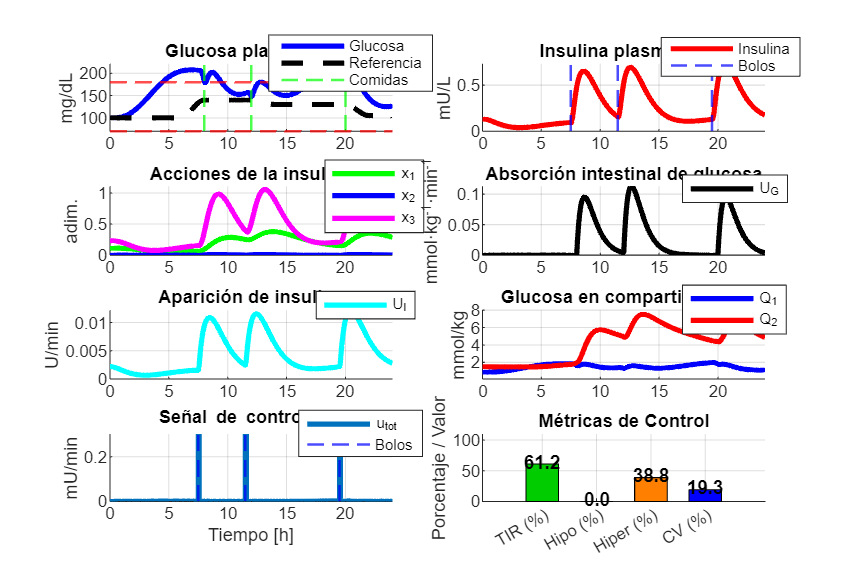



subplot(4, 2, 2);
hold on;
grid on;
plot(t_h, I_pl, 'r', 'LineWidth', LW);
for b = bolus_t
    xline(b / 60, '--b', 'LineWidth', 1.2);
end
xlim([0.0 24])
title('Insulina plasmática');
ylabel('mU/L');
legend({'Insulina', 'Bolos'}, 'Location', 'northoutside');

subplot(4, 2, 3);
hold on;
grid on;
plot(t_h, x1, 'g', 'LineWidth', LW);
plot(t_h, x2, 'b', 'LineWidth', LW);
plot(t_h, x3, 'm', 'LineWidth', LW);
xlim([0.0 24])
title('Acciones de la insulina');
ylabel('adim.');
legend({'x_1', 'x_2', 'x_3'}, 'Location', 'northoutside');

subplot(4, 2, 4);
hold on;
grid on;
plot(t_h, UG_series, 'k', 'LineWidth', LW);
xlim([0.0 24])
title('Absorción intestinal de glucosa');
ylabel('mmol·kg^{-1}·min^{-1}');
legend({'U_G'}, 'Location', 'northoutside');

subplot(4, 2, 5);
hold on;
grid on;
plot(t_h, UI_series, 'c', 'LineWidth', LW);
xlim([0.0 24])
title('Aparición de insulina');
ylabel('U/min');
legend({'U_I'}, 'Location', 'northoutside');

subplot(4, 2, 6);
hold on;
grid on;
plot(t_h, Q1_series, 'b', 'LineWidth', LW);
plot(t_h, Q2_series, 'r', 'LineWidth', LW);
xlim([0.0 24])
title('Glucosa en compartimentos');
ylabel('mmol/kg');
legend({'Q_1', 'Q_2'}, 'Location', 'northoutside');
xlim([0.0 24])
ylim([0.1 8.0])


subplot(4, 2, 7);
hold on;
grid on;
plot(t_h, u_tot, 'LineWidth', LW);
for b = bolus_t
    xline(b / 60, '--b', 'LineWidth', 1.2);
end
title('Señal de control u_{tot}');
ylabel('mU/min');
xlabel('Tiempo [h]');
xlim([0.0 24])
legend({'u_{tot}', 'Bolos'}, 'Location', 'northoutside');


subplot(4,2,8); cla; hold on; grid on;

vals = [TIR_pct, HIPO_pct, HIPER_pct, CV_pct];
bh   = bar(vals, 'FaceColor','flat', 'BarWidth',0.6);

bh.CData = [ 0 0.8 0 ;        % TIR
             1 0   0 ;        % Hipo
             1 0.5 0 ;        % Hiper
             0 0   1 ];       % CV

for i = 1:numel(vals)
    text(i, vals(i)+2, sprintf('%.1f', vals(i)), ...
        'HorizontalAlignment','center', ...
        'FontWeight','bold', 'FontSize',9);
end

set(gca, 'XTick', 1:4, ...
         'XTickLabel', {'TIR (%)','Hipo (%)','Hiper (%)','CV (%)'});
ylabel('Porcentaje / Valor');
title('Métricas de Control');
ylim([0 110]);      

subplot(4,2,1)
legend(["Glucosa", "Referencia", "Comidas"], "Location", "none", "Position", [0.3716 0.8625 0.0867 0.0513])
subplot(4,2,2)
legend(["Insulina", "Bolos"], "Location", "none", "Position", [0.8275 0.8809 0.0742 0.0356])
subplot(4,2,3)
legend(["x_1", "x_2", "x_3"], "Location", "none", "Position", [0.4166 0.6211 0.0525 0.0617])
subplot(4,2,4)
legend(["U_G"], "Location", "none", "Position", [0.8413 0.6528 0.0559 0.0235])
subplot(4,2,5)
legend(["U_I"], "Location", "none", "Position", [0.4058 0.4480 0.0527 0.0235])
subplot(4,2,6)
legend(["Q_1", "Q_2"], "Location", "none", "Position", [0.8415 0.4297 0.0550 0.0426])
subplot(4,2,7)
legend(["u_{tot}", "Bolos"], "Location", "none", "Position", [0.3934 0.2121 0.0658 0.0391])

El análisis de las gráficas y métricas revela que el controlador PID logra mantener la glucosa dentro del rango deseado (70–180 mg/dL) el 61,2 % del tiempo (TIR), evitando completamente episodios de hipoglucemia. Sin embargo, un 38,8 % del tiempo se permanece en estado de hiperglucemia, especialmente tras las comidas. Esto se debe a que, aunque la señal de control incluye bolos aplicados antes de cada ingesta, estos no son suficientes para compensar completamente la absorción rápida de glucosa intestinal. Además, la señal de insulina basal que genera el PID se mantiene cerca de cero entre comidas, lo que limita la acción correctiva sostenida frente a las perturbaciones.

En términos dinámicos, se observa una respuesta coherente entre la absorción de glucosa (U_G), la aparición de insulina (U_I), las acciones fisiológicas de la insulina (x₁, x₂, x₃) y las masas de glucosa en compartimentos. Las acciones insulínicas se elevan después de cada bolo, contribuyendo a reducir la glucosa plasmática, pero no lo hacen con la suficiente rapidez o magnitud para prevenir los picos glucémicos, especialmente cuando la carga de carbohidratos es elevada. La glucosa tisular acumulada en el compartimento lento también contribuye a mantener niveles altos durante varias horas, dificultando un retorno más eficiente al valor de referencia.

Finalmente, las métricas de desempeño como IAE (66 931), ISE (4,33 × 10⁶) e ITAE (4,93 × 10⁷) indican una respuesta global con errores acumulados significativos, tanto absolutos como ponderados en el tiempo. El coeficiente de variación del 19,3 % sugiere una variabilidad moderada, pero todavía lejos de un control óptimo. En conjunto, el sistema PID ofrece un control aceptable en términos de seguridad, evitando hipoglucemias, pero con limitaciones importantes para mitigar los picos post-prandiales, lo que sugiere la necesidad de controladores más anticipativos o adaptativos, como un MPC, para mejorar la regulación glucémica en escenarios realistas.

Esta función define una referencia de glucosa ideal que varía a lo largo del día, simulando objetivos clínicos realistas. Tiene tramos constantes durante la noche, aumentos suaves antes de las comidas y descensos graduales durante el resto del día. Las transiciones entre niveles se realizan mediante funciones cúbicas suavizadas para evitar cambios bruscos que podrían desestabilizar el controlador. Esta referencia es utilizada tanto por el PID como para el cálculo de los errores en los índices de desempeño.Esta función define una referencia de glucosa ideal que varía a lo largo del día, simulando objetivos clínicos realistas. Tiene tramos constantes durante la noche, aumentos suaves antes de las comidas y descensos graduales durante el resto del día. Las transiciones entre niveles se realizan mediante funciones cúbicas suavizadas para evitar cambios bruscos que podrían desestabilizar el controlador. Esta referencia es utilizada tanto por el PID como para el cálculo de los errores en los índices de desempeño.

function ref_val = smooth_glucose_reference(t_min)
    t_hour = mod(t_min / 60, 24);
    if t_hour < 6
        ref_val = 100;
    elseif t_hour < 8
        alpha = (t_hour - 6) / 2;
        ref_val = 100 + (140 - 100) * (3 * alpha^2 - 2 * alpha^3);
    elseif t_hour < 12
        ref_val = 140;
    elseif t_hour < 14
        alpha = (t_hour - 12) / 2;
        ref_val = 140 + (130 - 140) * (3 * alpha^2 - 2 * alpha^3);
    elseif t_hour < 20
        ref_val = 130;
    elseif t_hour < 22
        alpha = (t_hour - 20) / 2;
        ref_val = 130 + (105 - 130) * (3 * alpha^2 - 2 * alpha^3);
    else
        ref_val = 105;
    end
end

function ds = rhs_closed(t, s, Kp, Ki, Kd, p, ...
                          mt, cg, BW, bt, bU, blen, ...
                          u_maxPID, u_maxBOL)
    x = s(1:8);     % Variables de estado
    int_e = s(9);   

    ref = smooth_glucose_reference(t) / 18; % Glucosa de referencia en mmol/L
    e = ref - x(1) / p.VG;                

    UG = Ra_meal(t, mt, cg, p, BW);         % Absorción de glucosa de las comidas
    de = -dQ1_only(x, UG, p) / p.VG;       

    u_PID = Kp * e + Ki * int_e + Kd * de;  % Salida del control PID
    u_PID = max(0, min(u_PID, u_maxPID));   % Saturar salida PID

    u_bol = min(u_bolus(t, bt, bU, blen), u_maxBOL); % Insulina en bolo
    u_tot = u_PID + u_bol;                  % Entrega total de insulina

    dx = hovorka_rhs_meal(x, u_tot, UG, p); % Derivadas del modelo de Hovorka
    ds = [dx; e];                           % Derivadas combinadas (estados y error integral)
end

Esta función modela la tasa de aparición de glucosa intestinal como respuesta a las comidas, siguiendo la cinética propuesta por Hovorka. Convierte los gramos de carbohidratos ingeridos en una tasa de aparición de glucosa normalizada en función del peso corporal (en mmol/kg/min). Internamente utiliza una función tipo gamma que depende del tiempo transcurrido desde la ingesta, lo que permite simular de forma realista la absorción progresiva de la glucosa en el intestino.

% --- Tasa de absorción de glucosa de la comida (Ra_meal) ---
function UG = Ra_meal(t, mt, cg, p, BW)
    UG = 0;
    for k = 1:numel(mt)
        tau = t - mt(k);
        if tau > 0
            D = cg(k) * 1000 / 180 / BW; % Convertir g CHO a mmol/kg
            UG = UG + D * p.AG / p.tmaxG * (tau / p.tmaxG) .* exp(1 - tau / p.tmaxG);
        end
    end
end

% --- Tasa de entrega de insulina en bolo (u_bolus) ---
function u = u_bolus(t, bt, bU, blen)
    u = 0;
    for k = 1:numel(bt)
        if t >= bt(k) && t < bt(k) + blen
            u = bU(k) / blen;
        end
    end
end

function dQ1 = dQ1_only(x, UG, p)
    Q1 = x(1);
    Q2 = x(2);
    x1 = x(6);
    x3 = x(8);
    G = Q1 / p.VG;
    F01c = p.F01 * (G >= 4.5) + p.F01 * G / 4.5 * (G < 4.5);
    dQ1 = -(F01c / (p.VG * G) + x1) * Q1 + p.k12 * Q2 + UG + p.EGP0 * (1 - x3);
end

function dx = hovorka_rhs_meal(x, u, UG, p)
    Q1 = x(1); Q2 = x(2); S1 = x(3); S2 = x(4); I = x(5);
    x1 = x(6); x2 = x(7); x3 = x(8);
    G = Q1 / p.VG;
    F01c = p.F01 * (G >= 4.5) + p.F01 * G / 4.5 * (G < 4.5);
    UI = S2 / p.tmaxI;

    dQ1 = -(F01c / (p.VG * G) + x1) * Q1 + p.k12 * Q2 + UG + p.EGP0 * (1 - x3);
    dQ2 = x1 * Q1 - (p.k12 + x2) * Q2;
    dS1 = u - S1 / p.tmaxI;
    dS2 = S1 / p.tmaxI - S2 / p.tmaxI;
    dI = UI / p.VI - p.ke * I;
    dx1 = -p.ka1 * x1 + p.kb1 * I;
    dx2 = -p.ka2 * x2 + p.kb2 * I;
    dx3 = -p.ka3 * x3 + p.kb3 * I;
    dx = [dQ1; dQ2; dS1; dS2; dI; dx1; dx2; dx3];
end

Esta función calcula la señal de control total de insulina que entra al cuerpo en un instante dado. Combina el caudal basal de insulina generado por el PID con el efecto de los bolos de insulina administrados antes de cada comida. Se asegura de que ambas contribuciones estén limitadas por los máximos permitidos para mantener la fisiología del sistema. El resultado es una señal de control realista que se aplica al modelo de absorción subcutánea.

function u = u_total(t, row, Kp, Ki, Kd, p, mt, cg, BW, bt, bU, blen, u_maxPID, u_maxBOL)
    x = row(1:8);
    int_e = row(9);

    ref = smooth_glucose_reference(t) / 18;
    e = ref - x(1) / p.VG;

    UG = Ra_meal(t, mt, cg, p, BW);
    de = -dQ1_only(x, UG, p) / p.VG;

    u_PID = max(0, min(Kp * e + Ki * int_e + Kd * de, u_maxPID));
    u_b = min(u_bolus(t, bt, bU, blen), u_maxBOL);
    u = u_PID + u_b;
end

function [A, B, C, D, x_eq, ub, p] = linearizar_hovorka()
    % Parámetros del modelo
    p.k12 = 0.066;
    p.ka1 = 0.006;
    p.ka2 = 0.06;
    p.ka3 = 0.03;
    p.ke = 0.138;
    p.VI = 0.12;
    p.VG = 0.16;
    p.AG = 0.80;
    p.tmaxG = 40;
    p.kb1 = 51.2e-4;
    p.kb2 = 8.2e-4;
    p.kb3 = 520e-4;
    p.EGP0 = 0.0161;
    p.F01 = 0.0097;
    p.tmaxI = 55;

    Gss = 100 / 18; % Glucosa en estado estacionario
    Q1t = Gss * p.VG; 

    % Suposición inicial para fsolve
    x0 = [Q1t Q1t 1 1 5 0.1 0.1 0.1 0.01]';

    sol = fsolve(@(z) steady(z, p, Q1t), x0, optimoptions('fsolve', 'Display', 'none'));

    Q1 = sol(1); Q2 = sol(2); S1 = sol(3); S2 = sol(4); I = sol(5);
    x1 = sol(6); x2 = sol(7); x3 = sol(8); ub = sol(9);
    x_eq = [Q1; Q2; S1; S2; I; x1; x2; x3];

    A = jac_fd(@(x) hov_rhs(0, x, ub, p), x_eq); % Matriz A
    B = jac_fd(@(u) hov_rhs(0, x_eq, u, p), ub); % Matriz B

    C = zeros(1, 8);
    C(1) = 1 / p.VG; 
    D = 0;          

    fprintf('Equilibrio 100 mg/dL → u_basal = %.4f U/min\n', ub);
end

% --- Ecuaciones de estado estacionario ---

function F = steady(z, p, Q1t)
    Q1 = z(1); Q2 = z(2); S1 = z(3); S2 = z(4); I = z(5);
    x1 = z(6); x2 = z(7); x3 = z(8); ub = z(9);
    G = Q1 / p.VG;

    F01c = p.F01 * (G >= 4.5) + p.F01 * G / 4.5 * (G < 4.5);
    UI = S2 / p.tmaxI;

    dQ1 = -(F01c / (p.VG * G) + x1) * Q1 + p.k12 * Q2 + p.EGP0 * (1 - x3);
    dQ2 = x1 * Q1 - (p.k12 + x2) * Q2;
    dS1 = ub - S1 / p.tmaxI;
    dS2 = S1 / p.tmaxI - S2 / p.tmaxI;
    dI = UI / p.VI - p.ke * I;
    dx1 = -p.ka1 * x1 + p.kb1 * I;
    dx2 = -p.ka2 * x2 + p.kb2 * I;
    dx3 = -p.ka3 * x3 + p.kb3 * I;

    F = [dQ1; dQ2; dS1; dS2; dI; dx1; dx2; dx3; Q1 - Q1t];
end

function dx = hov_rhs(~, x, u, p)
    Q1 = x(1); Q2 = x(2); S1 = x(3); S2 = x(4); I = x(5);
    x1 = x(6); x2 = x(7); x3 = x(8);
    G = Q1 / p.VG;
    F01c = p.F01 * (G >= 4.5) + p.F01 * G / 4.5 * (G < 4.5);
    UI = S2 / p.tmaxI;

    dQ1 = -(F01c / (p.VG * G) + x1) * Q1 + p.k12 * Q2 + p.EGP0 * (1 - x3);
    dQ2 = x1 * Q1 - (p.k12 + x2) * Q2;
    dS1 = u - S1 / p.tmaxI;
    dS2 = S1 / p.tmaxI - S2 / p.tmaxI;
    dI = UI / p.VI - p.ke * I;
    dx1 = -p.ka1 * x1 + p.kb1 * I;
    dx2 = -p.ka2 * x2 + p.kb2 * I;
    dx3 = -p.ka3 * x3 + p.kb3 * I;
    dx = [dQ1; dQ2; dS1; dS2; dI; dx1; dx2; dx3];
end

% --- Jacobiano usando diferencias finitas (jac_fd) ---
function J = jac_fd(fun, x0, h)
    if nargin < 3
        h = 1e-6 * max(abs(x0), 1); % Tamaño de paso por defecto
    end
    x0 = x0(:); % Asegura que x0 sea un vector columna
    h = h(:);   % Asegura que h sea un vector columna
    f0 = fun(x0);
    m = numel(f0);  % Número de salidas
    n = numel(x0);  % Número de entradas
    J = zeros(m, n);

    for k = 1:n
        xp = x0;
        xm = x0;
        xp(k) = xp(k) + h(k);
        xm(k) = xm(k) - h(k);
        J(:, k) = (fun(xp) - fun(xm)) / (2 * h(k)); % Diferencia central
    end
end